# Trabajo Grupal 1: Generador Aleatorio de Escenarios de Super Mario Bros basado en dependencias.

Autores: Joan Camilo Peña, Jeisson Alejandro Hernandéz, Jhon Alejandro Morales.

## Objetivo.

Diseñar y proponer un generador aleatorio de escenarios de Super Mario Bros, basado en dependencias. 

## Introducción.

Actualmente los sistemas iterativos de funciones (IFS) por sus siglas en inglés, permiten establecer relaciones de unisimilitud de dos o más objetos mediante la iteración de transformaciones simples. Dichos sistemas se basan en un conjunto de funciones de transformación atados a un conglomerado de probabilidades para cada función en cuestión. En el presente trabajo se pretende establecer la dependecia que se genera cuando dos variables se encuentran relacionadas de alguna manera para la generación de mundos aleatorios del videojuego Super Mario Bros, apalancado por un IFS.

## Sistema Iterativo de Funciones.

Un IFS es un sistema dinámico de tiempo discreto en el que cada paso de tiempo (iteraciones) corresponde a la aplicación de un proceso y función sobre los cuales, unas variables o parámetros de entrada pueden sufrir cambios de acuerdo a la naturaleza que presentan. Las funciones construidas, representan distintos regímenes dinámicos de los cuales pueden seleccionarse de forma determinista o estocástica. Dada una serie de tiempo de un IFS, los algoritmos trabajados bajo esta definición son capaces de detectar el comportamiento que puede tener la siguiente marca de tiempo, de acuerdo a un conglomerado de probabilidades previamente deefinidas. Esta metodología tiene una amplia gama de usos potenciales: desde la detección de puntos de cambio en datos de series temporales hasta el campo de las comunicaciones digitales.

En el campo del desarrollo de videojuegos, la Generación de Contenido Procedural (PCG) gracias a su capacidad para crear entornos ricos y variados de forma automatizada. Un ejemplo notable es "MarioGPT", un proyecto que explora la generación de niveles para el icónico videojuego Super Mario Bros a través de Modelos de Lenguaje de Gran Escala (LLMs), demostrando contenido significativo que refleje intenciones y restricciones específicas, mientras se mantiene la capacidad de generar contenido de manera abierta y flexible (Sudhakaran, González-Duque, Freiberger, Glanois, Najarro, & Risi, 2022). Pero debido a su alta complejidad y costo computacional, se decide por aplicar un IFS que permite obtener resultados similares.

Por otro lado, en el análisis de datos, los modelos de Sistema Iterativo de Funciones han demostrado ser herramientas poderosas en la detección y separación de patrones dentro de conjuntos de datos complejos. Estos modelos ofrecen una nueva perspectiva en el análisis de series temporales y datos no lineales, permitiendo la identificación de dinámicas subyacentes y la separación de componentes con base en la repetición de transformaciones específicas (Alexander, Meiss, Bradley, & Garland, 2012).

En conjunto, estos ejemplos ilustran la versatilidad y el poder de los Sistemas Iterativos de Funciones en la generación de mundos virtuales y el análisis de datos complejos. Este trabajo se centra en explorar la dependencia generada entre variables al aplicar IFS en la generación de mundos aleatorios para Super Mario Bros, proporcionando así una contribución significativa a la comprensión y aplicación de estos sistemas en la generación de contenido dinámico y el análisis de datos.

## Actividades

### Actividad 1:

Codifiquen una función en MATLAB que, basándose únicamente en los dos elementos de la fila 12 de las últimas dos columnas de la matriz de los bloques, determine los siguientes dos bloques de esa fila. Para facilitar el proceso, permita que la función reciba dos matrices: una de 12x2, con las últimas dos columnas de la matriz de los bloques; y la otra, de 6x1, con la última columna de la matriz de tubos. La función que deben proponer debe retornar dos matrices: una de 12x2, con las filas 1 a 11, intactas; y la de tubos, sin ninguna alteración. Los bloques a generar en la fila 12 deben generarse aleatoriamente y solo pueden ser negro o baldosa.

Para dar solución a la primera actividad se plantea un diagrama de flujo que contendrá una matriz de probabilidades para la matriz de bloques. Teniendo en cuenta que las dos últimas columnas de la fila 12, pueden llevar valores de 1 o 2. **Es importante mencionar que cada una de las funciones desarrolladas, tiene como parámetros de entrada la matriz de bloques de 12x2 y la matriz de tubos de 6x1**.

Diagrama de Flujo propuesto:

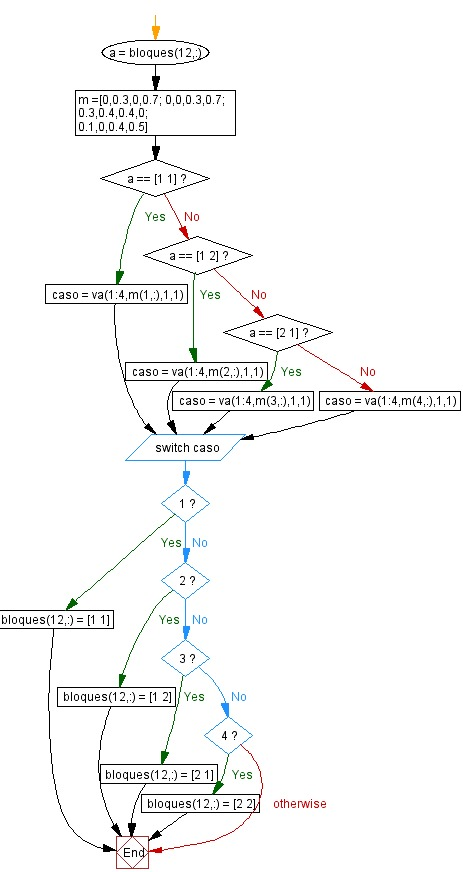

La función de la actividad1, la cual toma dos entradas: bloques y tubos. La función modifica y devuelve estas dos entradas basándose en una operación específica.

- **Extracción de la fila 12 de bloques:** La función comienza extrayendo la fila número 12 de la matriz bloques y la almacena en la variable a**.**

- **Definición de matriz de probabilidades m:** Luego, define una matriz de probabilidades m de 4x4, usada para determinar el comportamiento de la función.

- **Selección de un 'caso' basado en a:** La función evalúa la variable a (fila 12 de bloques) y, dependiendo de su valor, selecciona una fila específica de la matriz de probabilidades m para realizar una operación (mediante la función externa llamada va). La elección de la fila se basa en el valor de a comparado con cuatro posibles combinaciones: [1 1], [1 2], [2 1], [2 2].

- **Modificación de la fila 12 de bloques:** Según el resultado de la operación anterior (almacenado en caso), la función modifica la fila 12 de bloques a una de las cuatro posibles combinaciones mencionadas.

- **Retorno de bloques y tubos modificados:** Finalmente, la función devuelve las matrices bloques y tubos, habiendo modificado bloques según lo determinado por el proceso.

Se lleva el algoritmo a MATLAB usando la matriz de probabilidades inicial, descrita a continuación. Se dispone de una función llamada main que generá el mundo de mario, pasandole como parámetro el número de iteraciones deseadas, para nuestro caso el número es 40.

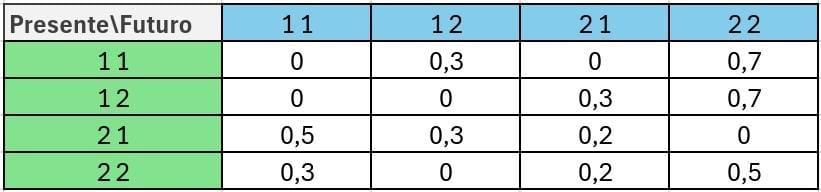

main(40);

De acuerdo a lo presenciado en la imagén, la actividad 1 presentaba demasiados espacios negros, por lo tanto se hace el reajuste de probabilidades, obteniendo la siguiente matriz.

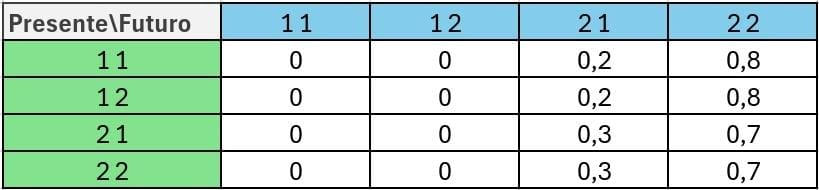

main(40);

main(40);

main(40);

### Actividad 2:

Codifiquen una función en MATLAB que, basándose únicamente en el elemento de la fila 6 de la última columna de la matriz de los tubos, determine la aparición o no del siguiente tubo. Para facilitar el proceso, permita que la función reciba dos matrices: una de 12x2, con las últimas dos columnas de la matriz de los bloques; y la otra, de 6x1, con la última columna de la matriz de tubos. La función que deben proponer debe retornar dos matrices: una de 12x2, con la misma matriz de bloques, sin alterar; y la de tubos, con las primeras cinco filas intactas, y solo con la modificación de la fila 6. El valor de la fila 6, debe generarse aleatoriamente y solo pueden ser 1 o 2.

Para dar solución a la segunda actividad se plantea un diagrama de flujo que contendrá una matriz de probabilidades para la matriz de tubos. Teniendo en cuenta que la última columna de la fila 6, pueden llevar valores de 1 o 2. **Es importante mencionar que cada una de las funciones desarrolladas, tiene como parámetros de entrada la matriz de bloques de 12x2 y la matriz de tubos de 6x1**.

Diagrama de Flujo propuesto:

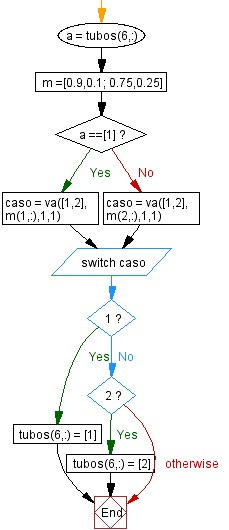

La función de la actividad2, que trabaja con dos matrices llamadas bloques y tubos. Al igual que en el ejemplo anterior, esta función modifica y devuelve estas matrices, aunque el foco aquí está en la modificación de la matriz tubos.

- **Toma de la fila 6 de tubos:** Inicialmente, la función extrae la fila número 6 de la matriz tubos y la guarda en la variable a.

- **Definición de la matriz de probabilidades m:** Se define una matriz m de 2x2, que representa otra matriz de probabilidades. Esta matriz se utiliza para decidir cómo modificar la fila 6 de tubos.

- **Decisión basada en a:** La función evalúa el valor de a (la fila 6 de tubos). Si a es igual a [1], entonces se selecciona la primera fila de la matriz de probabilidades m para determinar el "caso" mediante la función va. Si a es diferente de [1], entonces se selecciona la segunda fila de m para este propósito.

- **Modificación de la fila 6 de tubos:** Basado en el resultado obtenido de la función va (almacenado en la variable caso), la fila 6 de tubos se modifica a [1] o [2].

- **Retorno de las matrices modificadas:** La función finalmente devuelve las matrices bloques y tubos, habiendo modificado esta última.

Se lleva el algoritmo a MATLAB usando la matriz de probabilidades inicial, descrita a continuación. Se dispone de una función llamada main que generá el mundo de mario, pasandole como parámetro el número de iteraciones deseadas, para nuestro caso el número es 40. La actividad 2 incluye la actividad 1.

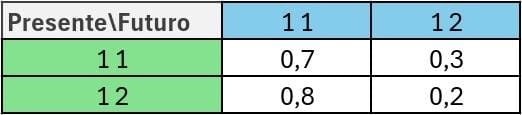

main(40);

De acuerdo a lo presenciado en la imagén, la actividad 2 presentaba demasiados tubos, por lo tanto se hace el reajuste de probabilidades, obteniendo la siguiente matriz.

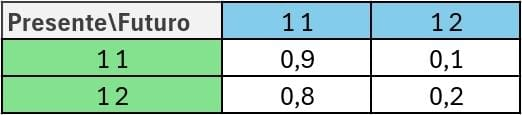

main(40);

main(40);

main(40);

### Actividad 3:

Codifiquen una función en MATLAB que, basándose únicamente en los dos elementos de la fila 8 de las últimas dos columnas de la matriz de los bloques, determine los siguientes dos bloques de esa fila. Para facilitar el proceso, permita que la función reciba dos matrices: una de 12x2, con las últimas dos columnas de la matriz de los bloques; y la otra, de 6x1, con la última columna de la matriz de tubos. La función que deben proponer debe retornar dos matrices: una de 12x2, con las filas 1 a 7, y 9 a 12, intactas; y la de tubos, sin ninguna alteración. Los bloques a generar en la fila 8 deben generarse aleatoriamente y solo pueden ser negro, interrogante o ladrillo.

Para dar solución a la tercera actividad se plantea un diagrama de flujo que contendrá una matriz de probabilidades para la matriz de bloques. Teniendo en cuenta que las dos últimas columnas de la fila 8, pueden llevar valores de 1,3 o 4. **Es importante mencionar que cada una de las funciones desarrolladas, tiene como parámetros de entrada la matriz de bloques de 12x2 y la matriz de tubos de 6x1**.

Diagrama de Flujo propuesto:

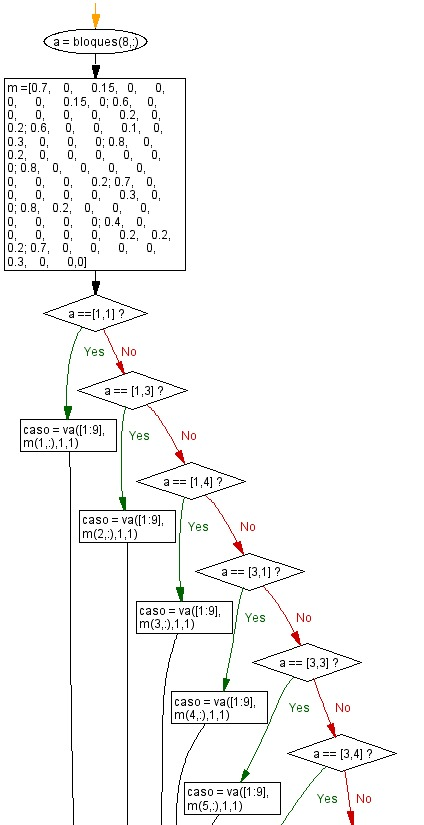

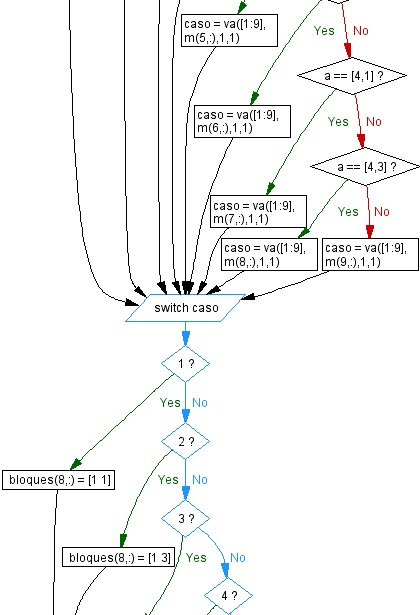

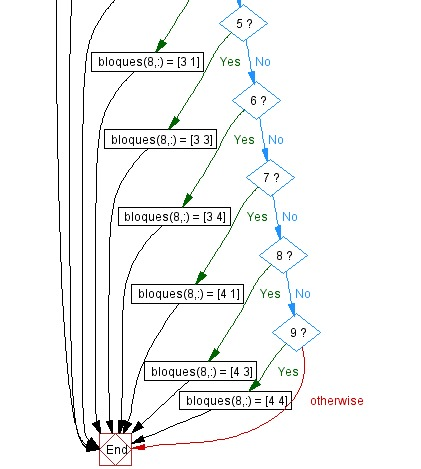

La función de la actividad3 modifica la fila 8 de la matriz bloques basándose en una distribución de probabilidades determinada por el estado actual de esa fila. Este estado se evalúa y, en función de él, se elige un nuevo estado de una serie de opciones predefinidas con probabilidades asociadas.

- **Extracción de la Fila 8:** La variable a captura el estado actual de la fila 8 de la matriz bloques. Este estado es crucial para determinar el conjunto de probabilidades a utilizar.

- **Matriz de Probabilidades m:** La matriz m define 9 diferentes distribuciones de probabilidades, cada una correspondiente a una configuración posible de a. Estas distribuciones guían la elección del nuevo estado de la fila 8.

- **Evaluación y Selección Basada en a**:                                                                                                                                                                                                    --> Dependiendo del valor de a, se selecciona una fila específica de m que corresponde a un conjunto de probabilidades.                                                              --> La función va se llama con este conjunto de probabilidades, generando un número del 1 al 9 que representa el "caso" o el nuevo estado a asignar a la fila 8, basándose en la distribución de probabilidades seleccionada.

- **Asignación del Nuevo Estado a la Fila 8:** Dependiendo del valor retornado por va (caso), se asigna un nuevo estado a la fila 8 de bloques. Cada "caso" de 1 a 9 tiene un estado correspondiente que se asigna a bloques(8,:).

- **Modificación Dinámica de bloques:**                                                                                                                                                                                                       --> Si a es [1 1], se usa la primera fila de m para determinar el nuevo estado.                                                                                                                                    --> Si a es [1 3], se usa la segunda fila de m, y así sucesivamente para otras configuraciones de a.                                                                                                          --> Si ninguna de las condiciones específicas se cumple, se utiliza la última fila de m por defecto.                                                                                                    --> La función va determina aleatoriamente el nuevo estado basándose en estas probabilidades, y bloques(8,:) se actualiza acorde a este resultado.

- **Resultado:** La función modifica la fila 8 de bloques introduciendo variabilidad en el sistema. Esta modificación no es arbitraria sino que sigue una distribución de probabilidades que puede ser ajustada para diferentes necesidades o comportamientos esperados.

Se lleva el algoritmo a MATLAB usando la matriz de probabilidades inicial, descrita a continuación. Se dispone de una función llamada main que generá el mundo de mario, pasandole como parámetro el número de iteraciones deseadas, para nuestro caso el número es 40. La actividad 3 incluye la actividad 1 y 2.

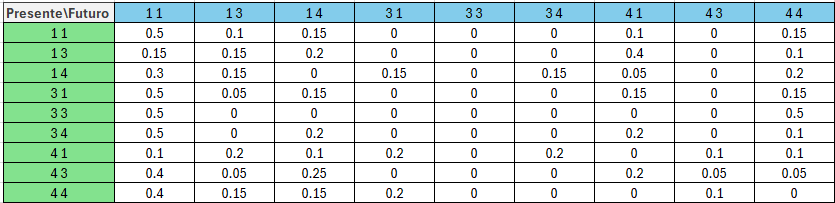

main(40);

De acuerdo a lo presenciado en la imagén, la actividad 3 presentaba demasiados ladrillos e interrogantes, por lo tanto se hace el reajuste de probabilidades, obteniendo la siguiente matriz.

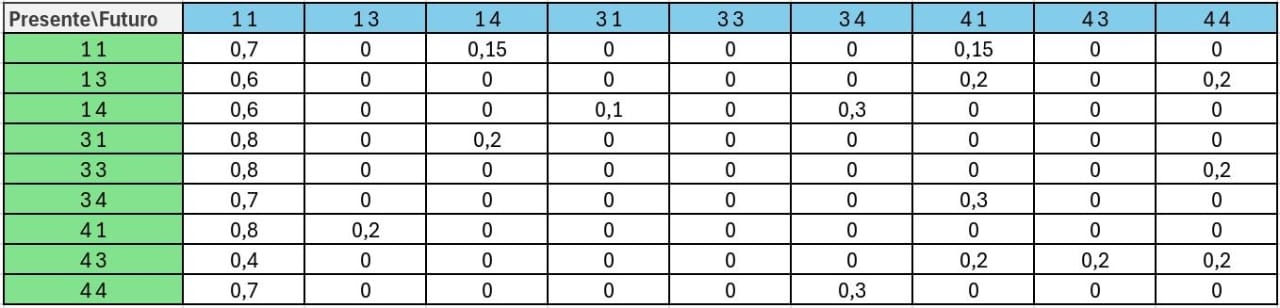

main(40);

main(40);

main(40);

### Actividad 4:

Codifiquen una función en MATLAB que, basándose únicamente en los dos elementos de la fila 4 de las últimas dos columnas de la matriz de los bloques, determine los siguientes dos bloques de esa fila. Para facilitar el proceso, permita que la función reciba dos matrices: una de 12x2, con las últimas dos columnas de la matriz de los bloques; y la otra, de 6x1, con la última columna de la matriz de tubos. La función que deben proponer debe retornar dos matrices: una de 12x2, con las filas 1 a 3, y 5 a 12, intactas; y la de tubos, sin ninguna alteración. Los bloques a generar en la fila 4 deben generarse aleatoriamente y solo pueden ser negro, interrogante o ladrillo.

Para dar solución a la cuarta actividad se plantea un diagrama de flujo que contendrá una matriz de probabilidades para la matriz de bloques. Teniendo en cuenta que las dos últimas columnas de la fila 4, pueden llevar valores de 1,3 o 4. **Es importante mencionar que cada una de las funciones desarrolladas, tiene como parámetros de entrada la matriz de bloques de 12x2 y la matriz de tubos de 6x1**.

Diagrama de Flujo propuesto:

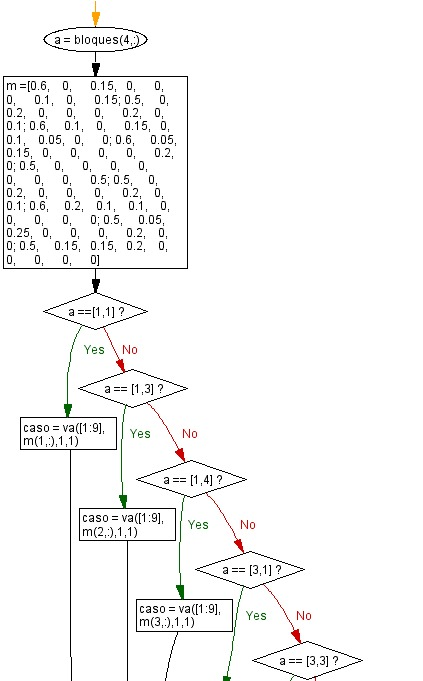

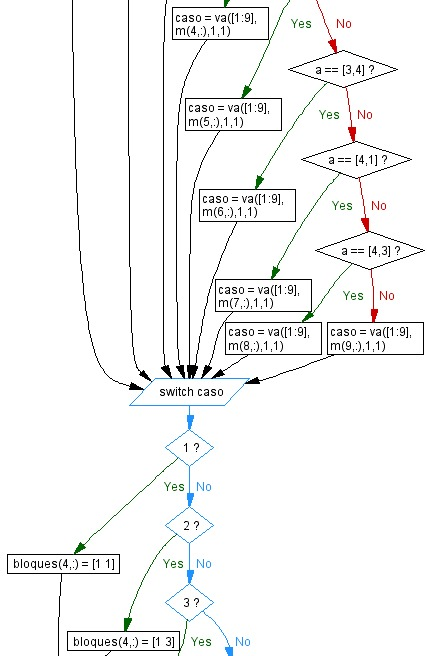

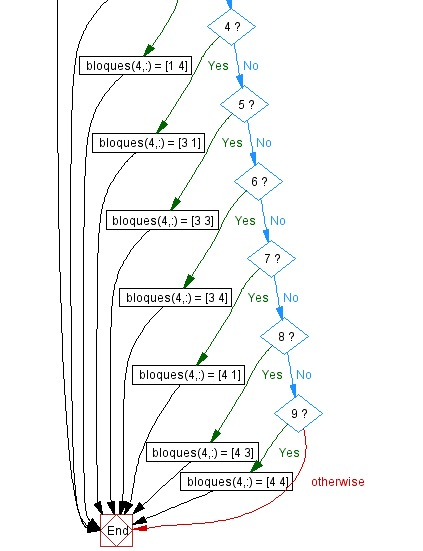

La función de la actividad4 modifica la fila 4 de la matriz bloques basándose en una distribución de probabilidades determinada por el estado actual de esa fila. Este estado se evalúa y, en función de él, se elige un nuevo estado de una serie de opciones predefinidas con probabilidades asociadas.

- **Extracción de la Fila 4:** La variable a captura el estado actual de la fila 4 de la matriz bloques. Este estado es crucial para determinar el conjunto de probabilidades a utilizar.

- **Matriz de Probabilidades m:** La matriz m define 9 diferentes distribuciones de probabilidades, cada una correspondiente a una configuración posible de a. Estas distribuciones guían la elección del nuevo estado de la fila 4.

- **Evaluación y Selección Basada en a**:                                                                                                                                                                                                    --> Dependiendo del valor de a, se selecciona una fila específica de m que corresponde a un conjunto de probabilidades.                                                              --> La función va se llama con este conjunto de probabilidades, generando un número del 1 al 9 que representa el "caso" o el nuevo estado a asignar a la fila 4, basándose en la distribución de probabilidades seleccionada.

- **Asignación del Nuevo Estado a la Fila 4:** Dependiendo del valor retornado por va (caso), se asigna un nuevo estado a la fila 8 de bloques. Cada "caso" de 1 a 9 tiene un estado correspondiente que se asigna a bloques(4,:).

- **Modificación Dinámica de bloques:**                                                                                                                                                                                                       --> Si a es [1 1], se usa la primera fila de m para determinar el nuevo estado.                                                                                                                                    --> Si a es [1 3], se usa la segunda fila de m, y así sucesivamente para otras configuraciones de a.                                                                                                          --> Si ninguna de las condiciones específicas se cumple, se utiliza la última fila de m por defecto.                                                                                                    --> La función va determina aleatoriamente el nuevo estado basándose en estas probabilidades, y bloques(4,:) se actualiza acorde a este resultado.

- **Resultado:** La función modifica la fila 4 de bloques introduciendo variabilidad en el sistema. Esta modificación no es arbitraria sino que sigue una distribución de probabilidades que puede ser ajustada para diferentes necesidades o comportamientos esperados.

Se lleva el algoritmo a MATLAB usando la matriz de probabilidades inicial, descrita a continuación. Se dispone de una función llamada main que generá el mundo de mario, pasandole como parámetro el número de iteraciones deseadas, para nuestro caso el número es 40. La actividad 4 incluye la actividad 1,2 y 3.

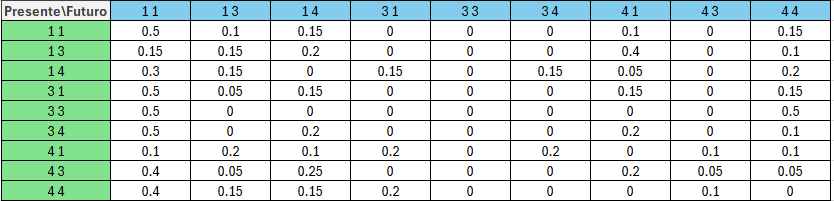

main(40);

De acuerdo a lo presenciado en la imagén, la actividad 4 presentaba demasiados ladrillos e interrogantes, por lo tanto se hace el reajuste de probabilidades, obteniendo la siguiente matriz.

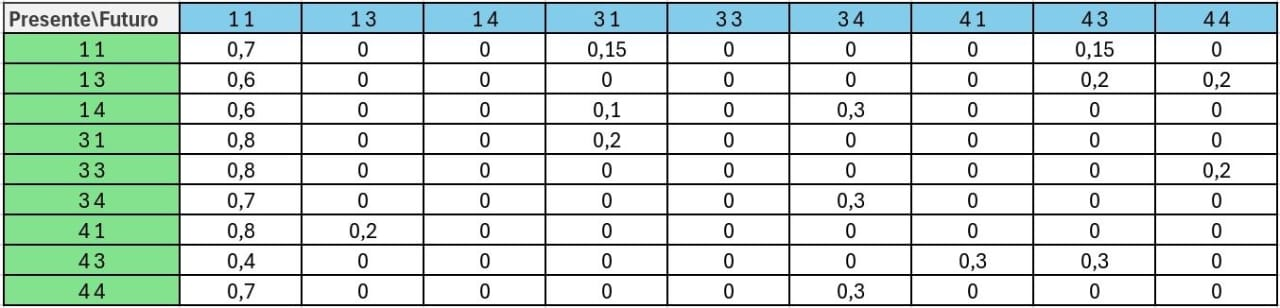

main(40);

main(40);

main(40);

### Actividad 5:

Codifiquen una función en MATLAB que, basándose únicamente en los dos elementos de la fila 3 de las últimas dos columnas de la matriz de los bloques, determine los siguientes dos bloques de esa fila. Para facilitar el proceso, permita que la función reciba dos matrices: una de 12x2, con las últimas dos columnas de la matriz de los bloques; y la otra, de 6x1, con la última columna de la matriz de tubos. La función que deben proponer debe retornar dos matrices: una de 12x2, con las filas 1 a 2, y 4 a 12, intactas; y la de tubos, sin ninguna alteración. Las monedas generadas en la fila 3, deben generarse aleatoriamente y solo pueden ser negro o moneda.

Para dar solución a la quinta actividad se plantea un diagrama de flujo que contendrá una matriz de probabilidades para la matriz de bloques. Teniendo en cuenta que las dos últimas columnas de la fila 3, pueden llevar valores de 1,5. **Es importante mencionar que cada una de las funciones desarrolladas, tiene como parámetros de entrada la matriz de bloques de 12x2 y la matriz de tubos de 6x1**. La función mariomundo sufre el siguiente cambio, con la siguiente línea.

a{5} =  imresize(imread('moneda1.png'), [16 16]);

Diagrama de Flujo propuesto:

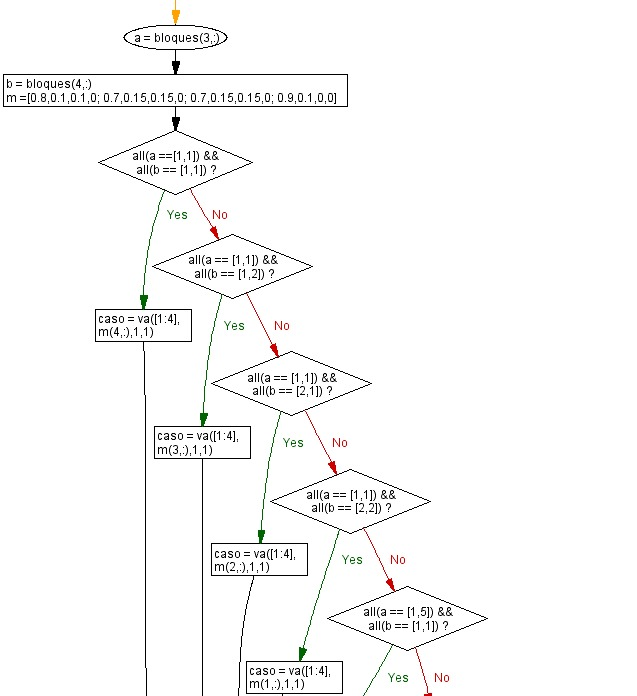

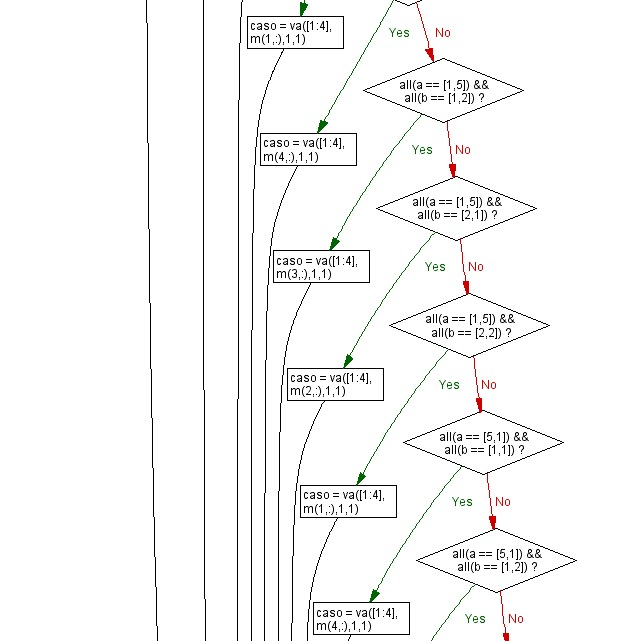

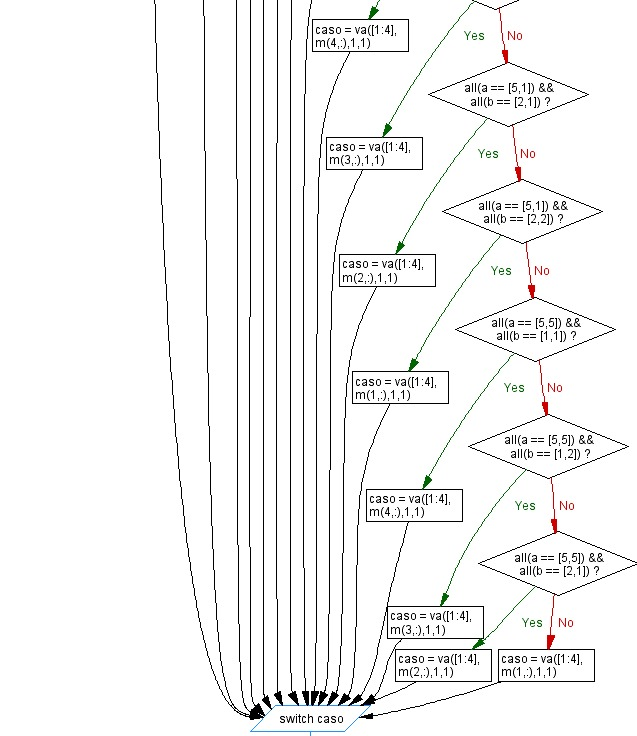

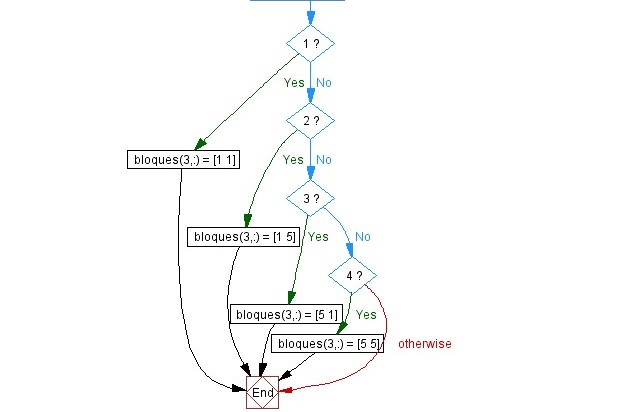

La función de la actividad5, la cual utiliza la función va para modificar las filas 3 y 4 de la matriz bloques basándose en condiciones específicas y una matriz de probabilidades.

- **Toma de las filas 3 y 4 de bloques:** Las variables a y b se utilizan para almacenar las filas 3 y 4 de la matriz bloques, respectivamente. Estas filas representan los estados actuales que influirán en la lógica de decisión de la función.

- **Matriz de Probabilidades m:** Se define una matriz m de 4x4, donde cada fila representa un conjunto distinto de probabilidades que se usarán para determinar cambios en la fila 3 de bloques bajo diferentes condiciones.

- **Lógica Condicional:**                                                                                                                                                                                                                               --> La función examina las combinaciones de valores en a (fila 3) y b (fila 4) para seleccionar un conjunto de probabilidades correspondiente de la matriz            --> Utiliza (all) para verificar si todos los elementos de a y b coinciden con los valores especificados en las condiciones. Esto asegura que se cumplan las condiciones exactas para cada combinación de a y b.                                                                                                                                                                         --> Basándose en la combinación de a y b, se elige una fila de m para determinar el "caso" usando la función va.

- **Generación de un Nuevo Estado con va:**                                                                                                                                                                                             --> va es llamada con el vector [1:4] como posibles valores y una fila de m como el conjunto de probabilidades, generando un valor (caso) que indica el nuevo estado a asignar a la fila 3 de bloques.

- **Asignación del Nuevo Estado:**                                                                                                                                                                                                              --> Dependiendo del "caso" generado por va, se asigna un nuevo estado a la fila 3 de bloques. Los estados posibles son [1 1], [1 5], [5 1], y [5 5], correspondientes a los casos del 1 al 4, respectivamente. 

- **Resultado:**                                                                                                                                                                                                                                                              --> La función modifica dinámicamente la fila 3 de bloques basándose en las condiciones iniciales de las filas 3 y 4 y en una matriz de probabilidades predefinida.                                                                                                                                                                                                                                                        --> Esta modificación se realiza de manera estocástica, permitiendo una variedad de resultados basados en las probabilidades definidas en m.

Se lleva el algoritmo a MATLAB usando la matriz de probabilidades inicial, descrita a continuación. Se dispone de una función llamada main que generá el mundo de mario, pasandole como parámetro el número de iteraciones deseadas, para nuestro caso el número es 40. La actividad 4 incluye la actividad 1,2,3 y 4.

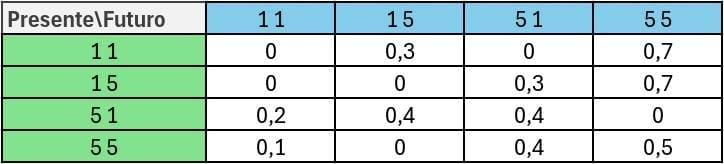

main(40);

De acuerdo a lo presenciado en la imagén, la actividad 5 presentaba demasiadas monedas contiguas, por lo tanto se hace el reajuste de probabilidades, obteniendo la siguiente matriz.

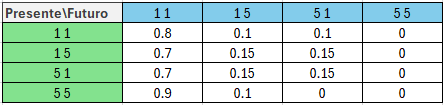

main(40);

main(40);

main(40);

### Actividad 6:

Codifiquen una función en MATLAB que, basándose únicamente en los dos elementos de la fila 6 de las últimas dos columnas de la matriz de los bloques, determine los siguientes dos bloques de esa fila. Para facilitar el proceso, permita que la función reciba dos matrices: una de 12x2, con las últimas dos columnas de la matriz de los bloques; y la otra, de 6x1, con la última columna de la matriz de tubos. La función que deben proponer debe retornar dos matrices: una de 12x2, con las filas 1 a 5, y 7 a 12, intactas; y la de tubos, sin ninguna alteración. Los koopas generados en la fila 6, deben generarse aleatoriamente y solo pueden ser negro o koopa.

Para dar solución a la sexta actividad se plantea un diagrama de flujo que contendrá una matriz de probabilidades para la matriz de bloques. Teniendo en cuenta que las dos últimas columnas de la fila 5,6 y 7, pueden llevar valores de 1,6. **Es importante mencionar que cada una de las funciones desarrolladas, tiene como parámetros de entrada la matriz de bloques de 12x2 y la matriz de tubos de 6x1**. La función mariomundo sufre el siguiente cambio, con la siguiente línea.

a{6} =  imresize(imread('koopa.png'), [16 16]);

Diagrama de Flujo propuesto:

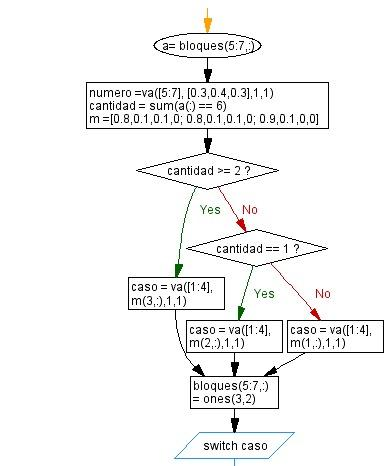

                       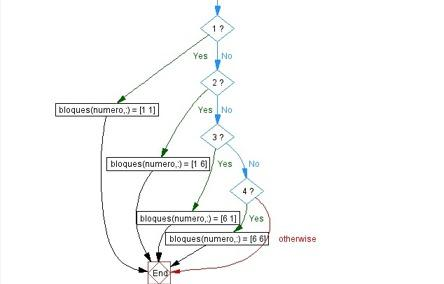

Función de la actividad6 que ajusta las filas de la matriz bloques basándose en la lógica condicional y en probabilidades definidas. Utilizando la función va para la selección aleatoria, modifica una fila específica dentro de bloques basada en las condiciones actuales de las filas 5,6 y 7.

- **Selección de Filas:** Se extraen las filas 5,6 y 7 (a) de la matriz bloques para usarlas como base en la lógica de decisión.

- **Selección Aleatoria de la Fila a Modificar:** Antes de decidir cómo modificar bloques, la función determina de forma aleatoria cuál fila modificará. Esto se hace mediante la llamada a va con los valores [5, 6, 7] y las probabilidades [0.3, 0.4, 0.3], seleccionando aleatoriamente entre estas filas con las probabilidades dadas. El resultado se guarda en número, indicando la fila de bloques que se modificará. Además, se genera una tributo llamado cantidad que almacena el número de veces que aparece el número 6.

- **Matriz de Probabilidades m:** Define las probabilidades para determinar el "caso" o acción a tomar basándose en las condiciones actuales de a.

- **Lógica Condicional Basada enel valor del atributo a:** De acuerdo al valor alojado en el atributo cantidad. Se determinará el de probabilidades a usar en la decisión de cómo modificar la matriz bloques.

- **Decisión de Modificación con va:** Usando la función va, la función elige un "caso" basado en las probabilidades seleccionadas de m. Este "caso" dicta cómo se modificará la fila de bloques determinada por número.

- **Modificación de la Matriz bloques:**                                                                                                                                                                                                         --> Según el "caso" retornado por va, se asigna un nuevo estado a la fila de bloques indicada por número.                                                                                                                                       --> Los estados posibles son [1 1], [1 6], [6 1], y [6 6], correspondiendo a los casos del 1 al 4, respectivamente.

- **Resultados:**                                                                                                                                                                                                                                            --> La función actualiza dinámicamente la fila especificada de bloques, introduciendo cambios basados en la interacción entre las filas 5,6 y 7 bajo una selección aleatoria que agrega un elemento estocástico a la lógica de modificación. --> Los matriz tubos no se modifica pero se devuelve como parte de la salida para mantener la firma de la función.

Se lleva el algoritmo a MATLAB usando la matriz de probabilidades inicial, descrita a continuación. Se dispone de una función llamada main que generá el mundo de mario, pasandole como parámetro el número de iteraciones deseadas, para nuestro caso el número es 40. La actividad 4 incluye la actividad 1,2,3,4 y 5.

main(40);

De acuerdo a lo presenciado en la imagén, la actividad 6 presentaba demasiados koopas contiguos, por lo tanto se hace el reajuste de probabilidades y limpiando la matriz bloques, obteniendo la siguiente matriz.

main(40);

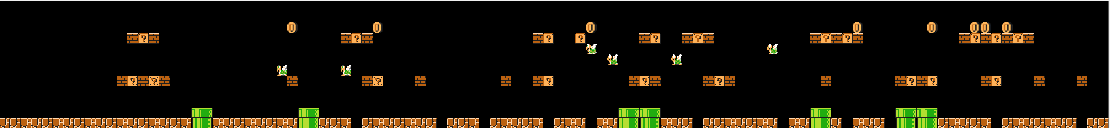

main(40);

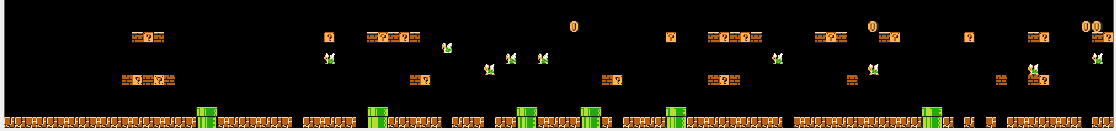

main(40);

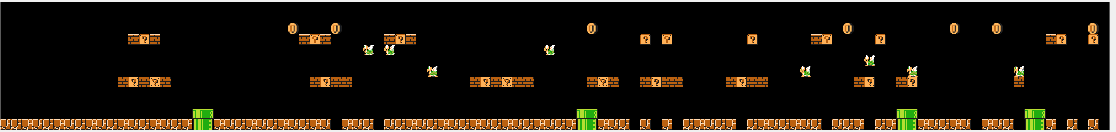

### Actividad 7:

Codifiquen una función en MATLAB que, basándose únicamente en los dos elementos de la fila 6 de las últimas dos columnas de la matriz de los bloques, determine los siguientes dos bloques de esa fila. Para facilitar el proceso, permita que la función reciba dos matrices: una de 12x2, con las últimas dos columnas de la matriz de los bloques; y la otra, de 6x1, con la última columna de la matriz de tubos. La función que deben proponer debe retornar dos matrices: una de 12x2, con las filas 1 a 9, y  12, intactas; y la de tubos, sin ninguna alteración. Las escalera son generadas en la fila 10 y 11, deben generarse aleatoriamente y solo pueden ser negro o escalera.

Para dar solución a la septima actividad se plantea un diagrama de flujo que contendrá una matriz de probabilidades para la matriz de bloques. Teniendo en cuenta que las dos últimas columnas de la fila 10 y 11, pueden llevar valores de 1,7. **Es importante mencionar que cada una de las funciones desarrolladas, tiene como parámetros de entrada la matriz de bloques de 12x2 y la matriz de tubos de 6x1**. La función mariomundo sufre el siguiente cambio, con la siguiente línea.

a{7} =  imresize(imread('escalera.png'), [16 16]);

Diagrama de Flujo propuesto:

               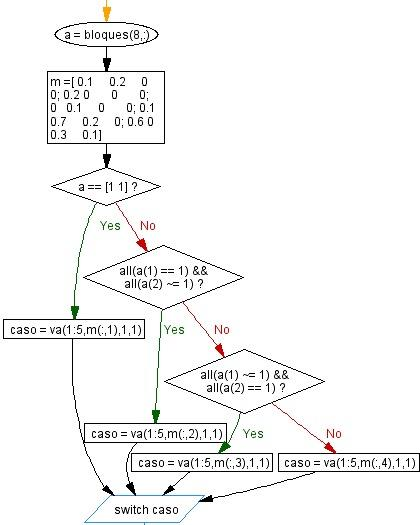

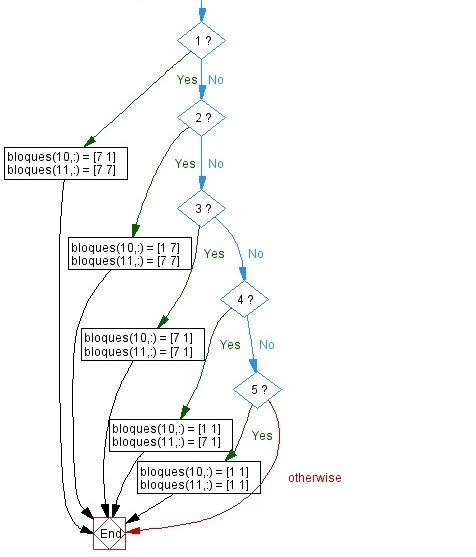

La función de la actividad7, podemos ver que la función modifica las filas 10 y 11 de la matriz bloques basada en el estado de la fila 8, utilizando una única matriz de probabilidades m. 

- **Análisis del Estado de la Fila 11:** La función comienza extrayendo el estado actual de la fila 11 de bloques y lo almacena en a.

- **Matriz de Probabilidades m:** Se crea una matriz de probabilidades m de 5x4, que define distintas probabilidades para determinar qué acción tomar en función del estado de a.

- **Determinación del Caso:**                                                                                                                                                                                         --> La función evalúa el estado de a y, dependiendo de este, selecciona una columna específica de m para usarla en la función va, determinando así el "caso" o acción a realizar.                                                                                                                                                         --> Si a es [1 1], se utiliza la primera columna de m.                                                                                                                                                          --> Si el primer elemento de a es 1 pero el segundo no lo es, se utiliza la segunda columna.                                                                                                                         --> Si el primer elemento de a no es 1 pero el segundo sí lo es, se utiliza la tercera columna.                                                                                                                           --> Para cualquier otro estado de a, se utiliza la cuarta columna de m.

- **Uso de la Función va:** va se llama con el rango 1:5 como posibles valores y la columna correspondiente de m como las probabilidades. Esto selecciona uno de los 5 casos basándose en las probabilidades dadas.

- **Modificación de las Filas 10 y 11 de bloques:** Dependiendo del caso seleccionado por va, se modifican las filas 10 y 11 de bloques:                                                                                                                                                                            --> Caso 1: Se establece la fila 10 a [7 1] y la fila 11 a [7 7].                                                                                                                                   --> Caso 2: Se establece la fila 10 a [1 7] y la fila 11 a [7 7].                                                                                                                                    --> Caso 3: Se establece la fila 10 a [7 1] y la fila 11 a [7 1].                                                                                                                                                         --> Caso 4: Se establece la fila 10 a [1 1] y la fila 11 a [7 1].                                                                                                                                       --> Caso 5: Se establece tanto la fila 10 como la 11 a [1 1].

- **Resultado:** La función finaliza con la matriz bloques modificada según las condiciones especificadas y las probabilidades definidas en m. Las modificaciones dependen estrechamente del estado inicial de la fila 8 y del resultado aleatorio proporcionado por va, demostrando una manera de introducir cambios controlados por probabilidades en estructuras de datos complejas.

Se lleva el algoritmo a MATLAB usando las matrices de probabilidades inicial, descrita a continuación. Se dispone de una función llamada main que generá el mundo de mario, pasandole como parámetro el número de iteraciones deseadas, para nuestro caso el número es 40. La actividad 4 incluye la actividad 1,2,3,4,5 y 6.

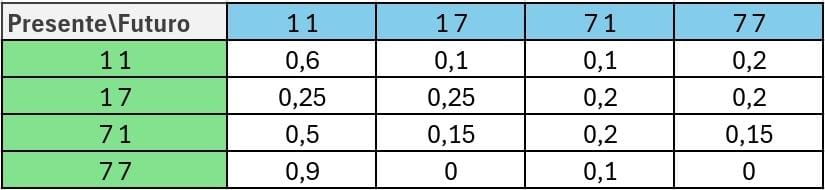

main(40);

De acuerdo a lo presenciado en la imagén, la actividad 7 presentaba demasiados escaleras, por lo tanto se hace el reajuste de probabilidades, obteniendo las siguientes matrices.

Matriz m:

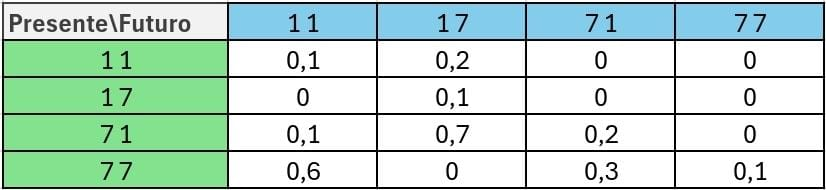

main(40);

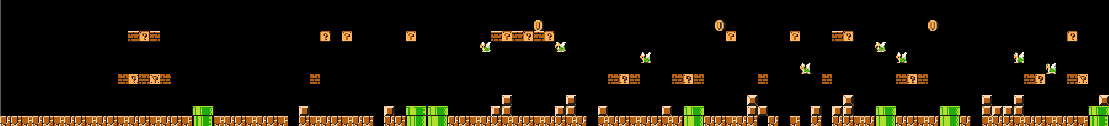

main(40);

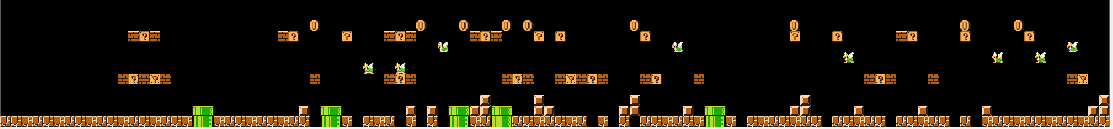

main(40);

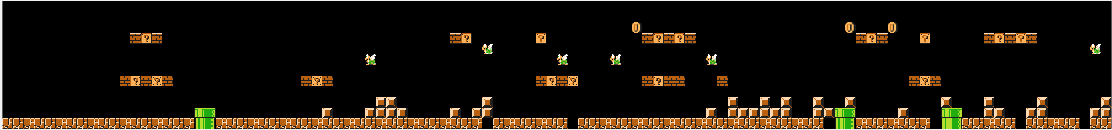

### Función de Distribución Acumulativa y Función de Densidad de Probabilidad.

- **La función de distribución** indica la probabilidad de que la variable aleatoria tenga un valor menor o igual que un cierto x. Por ello, también es conocida como función de probabilidad acumulada (Troncoso De La Cuesta et al., 2020).

- **La función de densidad** o simplemente **densidad** de una variable aleatoria mcontinua describe la probabilidad relativa según la cual dicha variable aleatoria tomará determinado valor. La probabilidad de que la variable aleatoria *caiga* en una región específica del espacio de posibilidades estará dada por la integral de la densidad de esta variable entre uno y otro límite de dicha región (Troncoso De La Cuesta et al., 2020).

Para la matriz de bloques, se presenta su función de distribución acumulativa y función de densidad de probabilidad después de ejecutarse las 7 actividades.

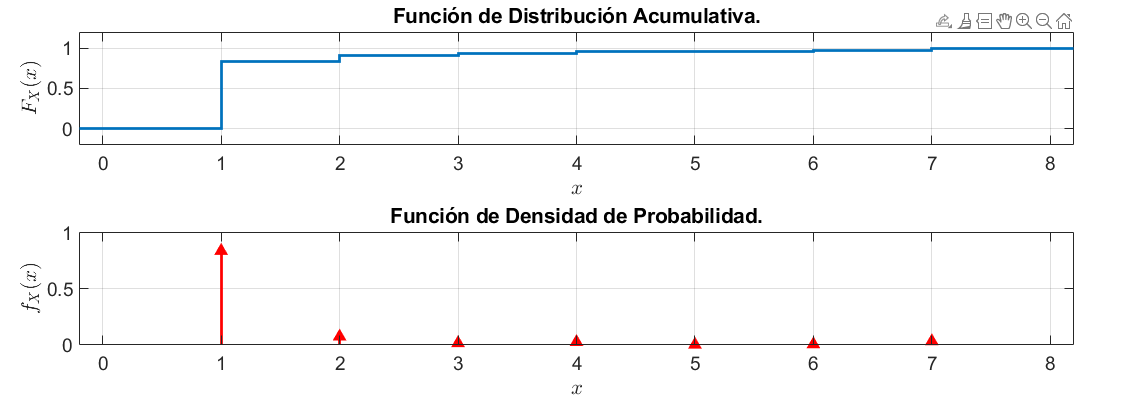

### Conclusiones.

- Estructurar un algoritmo de tipo SFI permite llevar a cabo un entregable de tipo correlacional y experimental que facilita percibir la posible sensibilidad del sistema a pequeñas perturbaciones en los parámetros de configuración alojados en el mismo. Esto permite predecir cómo se comportará el sistema en el futuro a partir de condiciones iniciales, lo que ocasiona la generación de mundos completamente diferentes en cada ejecución del programa principal expuesto en el documento.

- El dinamismo que permite la iteración continua y en secuencia de cada una de las 7 actividades describe el concepto de “atractor”; en donde las matrices de probabilidad presentadas en el trabajo realizado, toman las condiciones iniciales en las que se carga la matriz de bloques y tubos, logrando la generación de un mismo atractor, siendo este último generado para Mario.

- Una aplicación que pude resultar del trabajo expuesto, es la determinación del tipo de paquete que se ha trasmitido a lo largo de una red definida; donde se busca observar si se ha recibido un 1 o un 0 hasta un momento de tiempo determinado t, gracias al trabajo desarrollado por medio del SFI se podría construir un algoritmo que ponga a prueba la probabilidad condicional de haber transmitido un paquete x dado que recibí un paquete y; permitiendo calcular y tener muy en cuenta  el apriorí (probabilidad inicial de un evento ), su likelihood (probabilidad de observar la evidencia dada la verdad del evento) y el respectivo posteriori (probabilidad actualizada de un evento después de tener en cuenta la nueva evidencia). Para está aplicación sería indispensable tener en cuenta el BER (Bit Error Rate, tasa de error de bit) en español. Medida usada para indicar la cantidad de errores que ocurren durante la transmisión digital de información.

- Como trabajo futuro es posible plantear la generación de un mundo completamente jugable, donde los elementos como los koopa o monedas tengan movimiento y presenten físicas que interactúen y generen acciones cuando Mario pase cerca de ellos. Un proyecto de ese nivel podría ser alojado en la web y aquellos usuarios que decidan probar esta versión de Mario, no solo jueguen con los mundos aleatorios sino también puedan tener una sección para modificar las matrices de probabilidades para que construyan mundos con niveles de dificultad a gusto del jugador o inclusive agregar o remover sprites de forma dinámica.

- Los IFS se utilizan ampliamente para crear fractales y patrones complejos. La exploración de dependencias entre variables afectan la estética de los patrones generados su aplicación en campos como los videojuegos ; también los IFS tienen aplicaciones en la modelización científica, desde la física hasta la economía, donde los sistemas complejos y las dependencias entre variables juegan un papel crucial.

## Referencias 

1. Sudhakaran, S., González-Duque, M., Freiberger, M., Glanois, C., Najarro, E., & Risi, S. (2022). MarioGPT: Open-Ended Text2Level Generation through Large Language Models. [Nombre de la revista o conferencia, si está disponible].

2. Alexander, Z., Meiss, J. D., Bradley, E., & Garland, J. (2012). Iterated function system models in data analysis: Detection and separation. Chaos: An Interdisciplinary Journal of Nonlinear Science, 22(023103). 

3. Troncoso De La Cuesta, R., De, U., & De Compostela, S. (2020). *La distribución Gamma*.

## Anexos

 1. Repositorio de GitHub con todos los archivos usados para el desarrollo del trabajo. 

     https://github.com/alejomora999/HM_2024_Trabajo_1.git